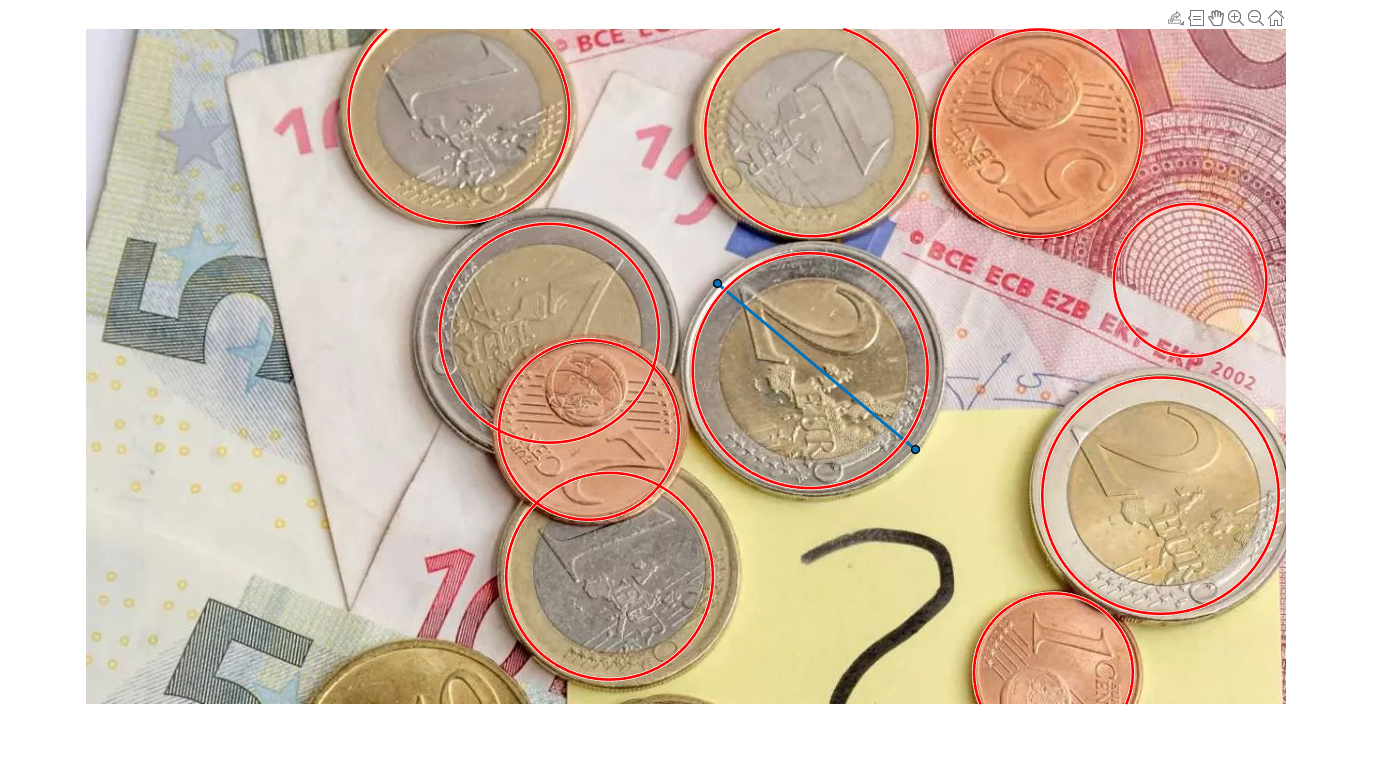

IOrig = imread("muenzenVerdeckung.jpg");
cells = cut(0, IOrig);

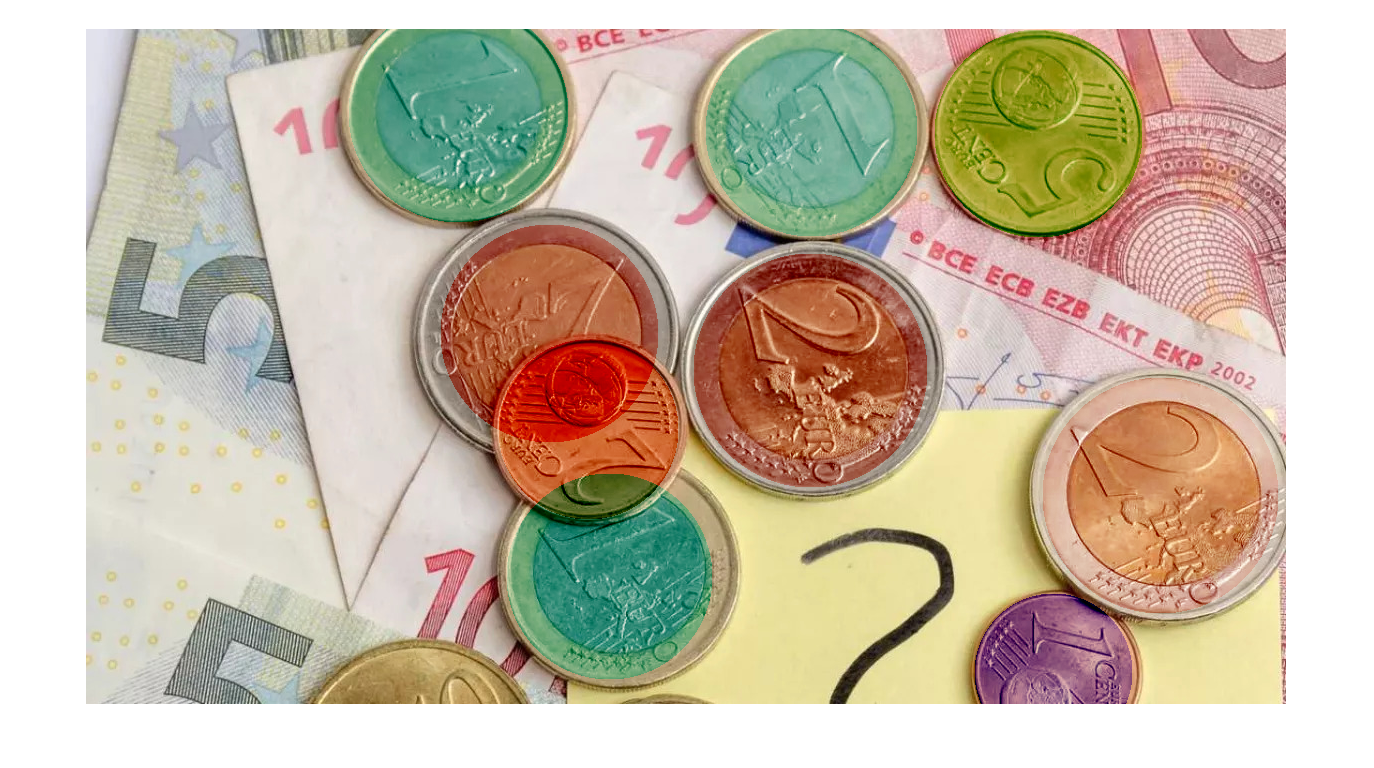

valueArray = [0.02, 2, 0.05, 0.01, 2, 0, 1, 2, 1, 1];
cells(:, 6) = num2cell(valueArray');
IProcessed = postwork(IOrig, cells, PostworkFilterType.NONE, 5.07);
imshow(IProcessed);

function y=postwork(I, cells, filterType, filterAmount)
    y = drawcellcircles(I, cells, filterType, filterAmount);
end

function z = drawcellcircles(I, cells, filterType, thresh)
    imagesize = size(I);
    centers = cell2mat(cells(:, 3:4));
    values = cell2mat(cells(:, 6));
    radii = cell2mat(cells(:, 5));

    extraFilter = false;

    indexArray = [];

    if filterType == PostworkFilterType.AMOUNT_MIN_COIN_COUNT
        indexArray = fittingCoinAmountMinCoinAmount(cells, thresh);
        extraFilter = true;
    end

    for i = 1 : size(values, 1)
        switch(filterType)
            case PostworkFilterType.MIN_AMOUNT
                if values(i) < thresh
                    continue
                end
            case PostworkFilterType.MAX_AMOUNT
                if values(i) > thresh
                    continue
                end
        end
        if extraFilter
            if ~ismember(i, indexArray)
                continue;
            end
        end



        x = centers(i, 1);
        y = centers(i, 2);
        r = radii(i);
        [xx, yy ] = ndgrid((1:imagesize(1))-y,(1:imagesize(2))-x);

        mask = uint8((xx.^2 + yy.^2)<(r^2)) * 255;
        IAdjusted = gcolorize(I, valueColor(values(i)));
        IAdjusted = imblend(I, IAdjusted, 1, 'linearburn');
        I = replacepixels(IAdjusted, I, mask);
    end
    z = I;
end

function y = fittingCoinAmountMinCoinAmount(cells, amount)

    values = cell2mat(cells(6));
    cent1  = sum(values(:) == 0.01);
    cent2  = sum(values(:) == 0.02);
    cent5  = sum(values(:) == 0.05);
    cent10 = sum(values(:) ==  0.1);
    cent20 = sum(values(:) ==  0.2);
    cent50 = sum(values(:) ==  0.5);
    euro1  = sum(values(:) ==    1);
    euro2  = sum(values(:) ==    2);

    remainder = amount * 100;

    euro2Amount = fix(remainder / 200);
    remainder = mod(remainder, 200);
    if euro2Amount > euro2
        needed = euro2Amount;
        euro2Amount = euro2;
        remainder = remainder + 200 * (needed - euro2Amount);
    end

    euro1Amount = fix(remainder / 100);
    remainder = mod(remainder, 100);
    if euro1Amount > euro1
        needed = euro1Amount;
        euro1Amount = euro1;
        remainder = remainder + 100 * (needed - euro1Amount);
    end

    cent50Amount = fix(remainder / 50);
    remainder = mod(remainder, 50);
    if cent50Amount > cent50
        needed = cent50Amount;
        cent50Amount = cent50;
        remainder = remainder + 50 * (needed - cent50Amount);
    end

    cent20Amount = fix(remainder / 20);
    remainder = mod(remainder, 20);
    if cent20Amount > cent20
        needed = cent20Amount;
        cent20Amount = cent20;
        remainder = remainder + 20 * (needed - cent20Amount);
    end

    cent10Amount = fix(remainder / 10);
    remainder = mod(remainder, 10);
    if cent10Amount > cent10
        needed = cent10Amount;
        cent10Amount = cent10;
        remainder = remainder + 10 * (needed - cent10Amount);
    end

    cent5Amount = fix(remainder / 5);
    remainder = mod(remainder, 5);
    if cent5Amount > cent5
        needed = cent5Amount;
        cent5Amount = cent5;
        remainder = remainder + 5 * (needed - cent5Amount);
    end

    cent2Amount = fix(remainder / 2);
    remainder = mod(remainder, 2);
    if cent2Amount > cent2
        needed = cent2Amount;
        cent2Amount = cent2;
        remainder = remainder + 2 * (needed - cent2Amount);
    end

    cent1Amount = fix(remainder / 1);
    remainder = mod(remainder, 1);
    if cent1Amount > cent1
        needed = cent1Amount;
        cent1Amount = cent1;
        remainder = remainder + 1 * (needed - cent1Amount);
    end

    indexArray = [];
    Arrsize = size(values, 1);

    count = 0;

    if remainder == 0
        for i = 1 : Arrsize
            if values(i) == 2
                indexArray = [indexArray, i];
                count = count + 1;
            end
            if count == euro2Amount
                break
            end
        end
        count = 0;
        for i = 1 : Arrsize
            if values(i) == 1
                indexArray = [indexArray, i];
                 count = count + 1;
            end
            if count == euro1Amount
                break
            end
        end
        count = 0;
        for i = 1 : Arrsize
            if values(i) == 0.5
                indexArray = [indexArray, i];
                 count = count + 1;
            end
            if count == cent50Amount
                break
            end
        end
        count = 0;
        for i = 1 : Arrsize
            if values(i) == 0.2
                indexArray = [indexArray, i];
            count = count + 1;
            end
            if count == cent20Amount
                break
            end
        end
        count = 0;
        for i = 1 : Arrsize
            if values(i) == 0.1
                indexArray = [indexArray, i];
            count = count + 1;
            end
            if count == cent10Amount
                break
            end
        end
        count = 0;
        for i = 1 : Arrsize
            if values(i) == 0.05
                indexArray = [indexArray, i];
            count = count + 1;
            end
            if count == cent5Amount
                break
            end
        end
        count = 0;
        for i = 1 : Arrsize
            if values(i) == 0.02
                indexArray = [indexArray, i];
            count = count + 1;
            end
            if count == cent2Amount
                break
            end
        end
        count = 0;
        for i = 1 : Arrsize
            if values(i) == 0.01
                indexArray = [indexArray, i];
            count = count + 1;
            end
            if count == cent1Amount
                break
            end
        end
        y = indexArray;
    else
        y = -1;
    end
end

function y=valueColor(value)
    switch (value)
        case 0.00
            y = [360, 100, 100];
        case 0.01
            y = [241, 100, 56];
        case 0.02
            y = [18,79,47];
        case 0.05
            y = [117, 100, 56];
        case 0.1
            y = [268, 100, 56];
        case 0.2
            y = [324, 100, 56];
        case 0.5
            y = [67,69,57];
        case 1
            y = [174. 100, 56];
        case 2
            y = [4,100,68];
    end
end
